# ECM307 - T1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Atividade T1 analogia entre vetores e sinais
%%
%% Nome: Luis Guilherme de Souza Munhoz
%% RA: 20.01937-8
%% Lab: 3
%%
%% 

clc;                % limpa a tela
clear all;          % limpar as variáveis
close all;          % fecha as figuras abertas


## Item 1

## 
$$g\left(t\right)=e^{-t}$$


## Item 2

## 
$$g_n \left(t\right)=e^{-\textrm{jn}\omega_0 t}$$


## Definindo variáveis e funções a serem estudadas

## Criando funções

syms t
%% Declaração de funções
gt = @(t) exp(-t);
gn = @(n,t) exp(-j*n*wo*t);

## Item 3

## Análise simbólica e numérica

%% Declarando e inicializando vaiáveis
syms t

T0 = 1;
N  = 10; 
n  = [-N:1:N]; 

for k = 1:2*N+1 

    gt = @(t) exp(-t);
    gn = @(n,t) exp(-j*n*2*pi*t);

    clc;

    c(k) = projecao(gt(t),gn(n(k),t),T0);

end

%% Determinação dos coeficientes c1 e c-1
c1 = projecao(gt(t),gn(1,t),T0)

c1 = 0.0156 - 0.0981i

c_menos1 = projecao(gt(t),gn(-1,t),T0)

c_menos1 = 0.0156 + 0.0981i


t = linspace(0,T0,1000);        % vetor tempo

%% Cálculo numérico da projeção p1 e resíduo r1
p1 = c1*gn(1,t) + c_menos1*gn(-1,t);
r1 = gt(t) - p1;

%% Comparando p1(t) com r1(t) e g(t)
figure()
plot(t,gt(t),'LineWidth',2), title('Comparação de g(t), r(t) e p(t) para n=1'); grid minor
hold; plot(t,p1,'LineWidth',2)

Current plot held


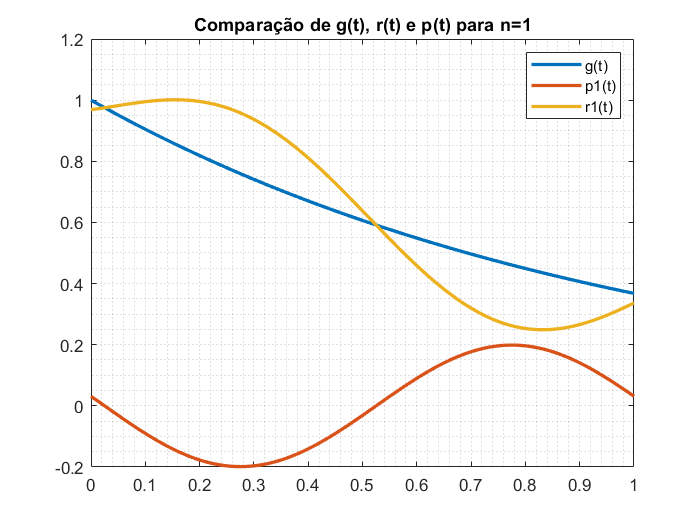

plot(t,r1,'LineWidth',2)
hold off
legend("g(t)", "p1(t)","r1(t)")

## Item 4

%% redefinição das variáveis como simbólicas
syms t p12
%% Determinação dos coeficientes c2 e c-2
c2 = projecao(gt(t),gn(2,t),T0)

c2 = 0.0040 - 0.0500i

c_menos2 = projecao(gt(t),gn(-2,t),T0)

c_menos2 = 0.0040 + 0.0500i


%% criação da função resíduo para cálculo de c2 e c-2 a partir do resíduo r1(t)
residuo = @(gt, p) gt - p12;


%% cálculo de c2 e c-2 a partir do resíduo r1(t)
c22 = projecao((residuo(gt(t),p12)),gn(2,t),T0)

c22 = 0.0040 - 0.0500i

c_menos22 = projecao((residuo(gt(t),p12)),gn(-2,t),T0)

c_menos22 = 0.0040 + 0.0500i

p12 = c1*gn(2,t) + c_menos1*gn(-2,t);
g = gt(t);

%% cálculo da diferença entre os diferentes c2 e c-2 calculados
difc2 = abs(c2-c22)

difc2 = 0

difcmenos2 = abs(c_menos2-c_menos22)

difcmenos2 = 0

disp('pode-se ver que a diferença entre os cálculos de c2 e cmenos 2 é 0 pois é uma ótima aproximação  ');

pode-se ver que a diferença entre os cálculos de c2 e cmenos 2 é 0 pois é uma ótima aproximação  


%% cálculo numérico da projeção p2 e resíduo r2
t = linspace(0,T0,1000);                     % vetor tempo
p2 = c2*gn(2,t) + c_menos2*gn(-2,t);
r2 = gt(t) - (p1 + p2);

%% comparando p2(t) e r2(t) com g(t)
figure()
plot(t,gt(t),'LineWidth',2), title('Comparação de g(t), r(t) e p(t) para n=2'); grid minor
hold; plot(t,p2,'LineWidth',2)

Current plot held


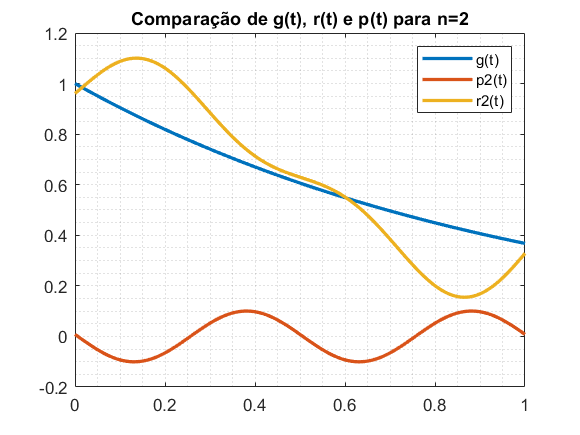

plot(t,r2,'LineWidth',2)
hold off
legend("g(t)", "p2(t)","r2(t)")

## Item 5

## cálculo iterativo

t = linspace(0,T0,1000);             % vetor tempo
w0    = 2*pi/T0;                     % frequência ângular
p0    = c(N+1);                      % projeção para n = 0

for k=1:N

    p(:,k) = c(N+1-k)*exp(j*n(N+1-k)*w0*t) + c(N+1+k)*exp(j*n(N+1+k)*w0*t);
    r(:,k) = gt(t)' - sum(p(:,k));

end

## exibindo o gráfico final e comparando g(t) pn(t) e rn(t)

figure()
plot(t,gt(t),'LineWidth',2), title('Comparação g(t) e p(t)'); grid minor
hold;

Current plot held


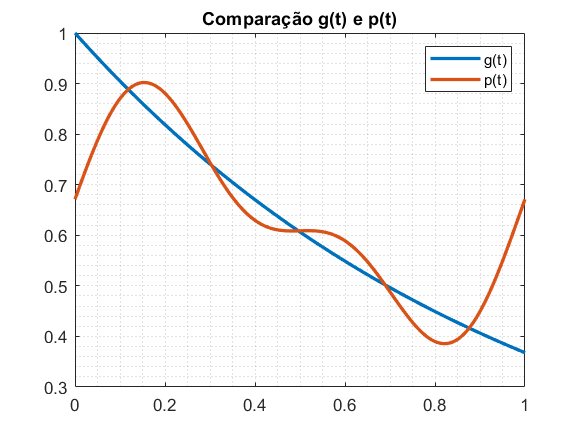

plot(t,sum(p')+p0,'LineWidth',2)
legend('g(t)','p(t)');

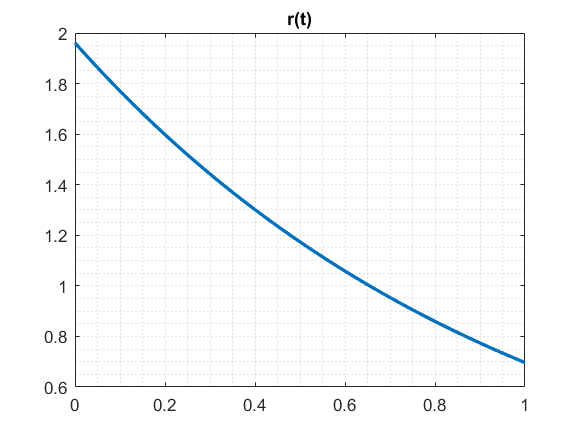

figure()
plot(t,sum(r'),'LineWidth',2), title('r(t)'); grid minor

## função projeção

function [c] = projecao(gt,gn,T0)

% calcula c

syms t

%%% Numerador

Num = int(gt*gn,t,0,T0);

%%% Denominador

Den = int(abs(gn)^2,t,0,T0);

%%% Projeção simbólica

cn = Num/Den;

%%% Projeção Numérica

c = eval(cn);

end